run01= load("sensorlog_r_01.mat")

run01 = struct with fields:
    Acceleration: [1603x3 timetable]
        Position: [31x6 timetable]


r_01 = run01.Position

r_01 = 31x6 timetable
        Timestamp        latitude    longitude    altitude    speed    course     hacc 
    _________________    ________    _________    ________    _____    ______    ______

    14-Jun-2025 11...     1.5589      103.64       15.747        0         0     10.287
    14-Jun-2025 11...     1.5589      103.64       15.974     0.69     208.3     10.282
    14-Jun-2025 11...     1.5589      103.64       16.914     0.58     174.4     10.211
    14-Jun-2025 11...     1.5589      103.64       17.183     0.36     171.6     10.182
    14-Jun-2025 11...     1.5588      103.64       17.647     0.61     164.2     10.362
    14-Jun-2025 11...


format shortG
latitude = r_01.latitude

latitude =        1.5589
       1.5589
       1.5589
       1.5589
       1.5588
       1.5588
       1.5588
       1.5588
       1.5588
       1.5588


longitude = r_01.longitude

longitude =        103.64
       103.64
       103.64
       103.64
       103.64
       103.64
       103.64
       103.64
       103.64
       103.64


altitude = r_01.altitude

altitude =        15.747
       15.974
       16.914
       17.183
       17.647
       17.459
       17.162
       17.288
       17.015
       16.574


speed = r_01.speed

speed =             0
         0.69
         0.58
         0.36
         0.61
         0.99
         0.94
         1.03
         0.42
         0.42


course = r_01.course

course =             0
        208.3
        174.4
        171.6
        164.2
        160.9
        154.7
        129.7
        109.1
         58.9


hacc = r_01.hacc

hacc =        10.287
       10.282
       10.211
       10.182
       10.362
       10.467
       10.631
       10.676
         10.7
       10.843


runAcc = run01.Acceleration

runAcc = 1603x3 timetable
        Timestamp           X          Y         Z   
    _________________    ________    ______    ______

    14-Jun-2025 11...     0.48574    3.8584    8.8379
    14-Jun-2025 11...      1.4937    4.3663    9.1896
    14-Jun-2025 11...      1.6158    4.9502    8.9743
    14-Jun-2025 11...      1.8263    5.0124    8.5747
    14-Jun-2025 11...      1.9412     4.931    8.1529
    14-Jun-2025 11...      1.2897    4.5266    8.9049
    14-Jun-2025 11...     0.80638    4.0672     9.676
    14-Jun-2025 11...    -0.47916    3.8967    10.021
    14-Jun-2025 11...    -0.25184    4.2323    8.5029
    14-Jun-2025 11...    -0.45045    4.9549    6.8794
    14-Jun-

% Steps taken calculation
earthCirc = 24901;
totaldis = 0;

for i = 1: (length(latitude)-1)
lat1 = latitude(i); %This represents the first latitude
lat2 = latitude(i+1); %This will be the second latitude
lon1 = longitude(i);
lon2 = longitude(i+1);
diff = distance(lat1, lon1, lat2, lon2);
dis = (diff/360)*earthCirc;
totaldis = totaldis +dis;
end

stride = 2.5;
totaldis_ft = totaldis*5280;
steps = totaldis_ft/stride;

% Plot Graph
time = r_01.Timestamp

time = 31x1 datetime array
   14-Jun-2025 11:12:00.000
   14-Jun-2025 11:12:01.000
   14-Jun-2025 11:12:02.000
   14-Jun-2025 11:12:03.000
   14-Jun-2025 11:12:04.000
   14-Jun-2025 11:12:05.000
   14-Jun-2025 11:12:06.000
   14-Jun-2025 11:12:07.000
   14-Jun-2025 11:12:08.000
   14-Jun-2025 11:12:09.000
   14-Jun-2025 11:12:10.000
   14-Jun-2025 11:12:11.000
   14-Jun-2025 11:12:12.000
   14-Jun-2025 11:12:13.000
   14-Jun-2025 11:12:14.000
   14-Jun-2025 11:12:15.000
   14-Jun-2025 11:12:16.000
   14-Jun-2025 11:12:17.000
   14-Jun-2025 11:12:18.000
   14-Jun-2025 11:12:19.000
   14-Jun-2025 11:12:20.000
   14-Jun-2025 11:12:21.000
   14-Jun-2025 11:12:22.000
   14-Jun-2025 11:12:23.000
   14-Jun-2025 11:12:24.000
   14-Jun-2025 11:12:25.000
   14-Jun-2025 11:12:26.000
   14-Jun-2025 11:12:27.000
   14-Jun-2025 11:12:28.000
   14-Jun-2025 11:12:29.000



timeSec = timeElapsed(time)

timeSec =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


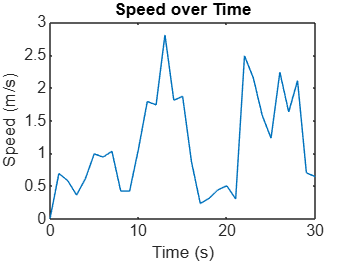

plot(timeSec, r_01.speed)
xlabel('Time (s)')
ylabel('Speed (m/s)')
title('Speed over Time')

% Calculating average speed

totKM = totaldis * 1.6034;
timeTot = seconds(time(end) - time(1)); 

avgSpeed = totKM / (timeTot/3600);

% For output checking
totKM

totKM =      0.036143


steps

steps =        47.608


avgSpeed

avgSpeed =        4.3372


% MET calculation

% Input from user
weight = input("What is your weight?");

MET_RUN = 7;

time_inhour = timeTot / 3600;
calories = MET_RUN * time_inhour * weight;

calories

calories =           3.5
